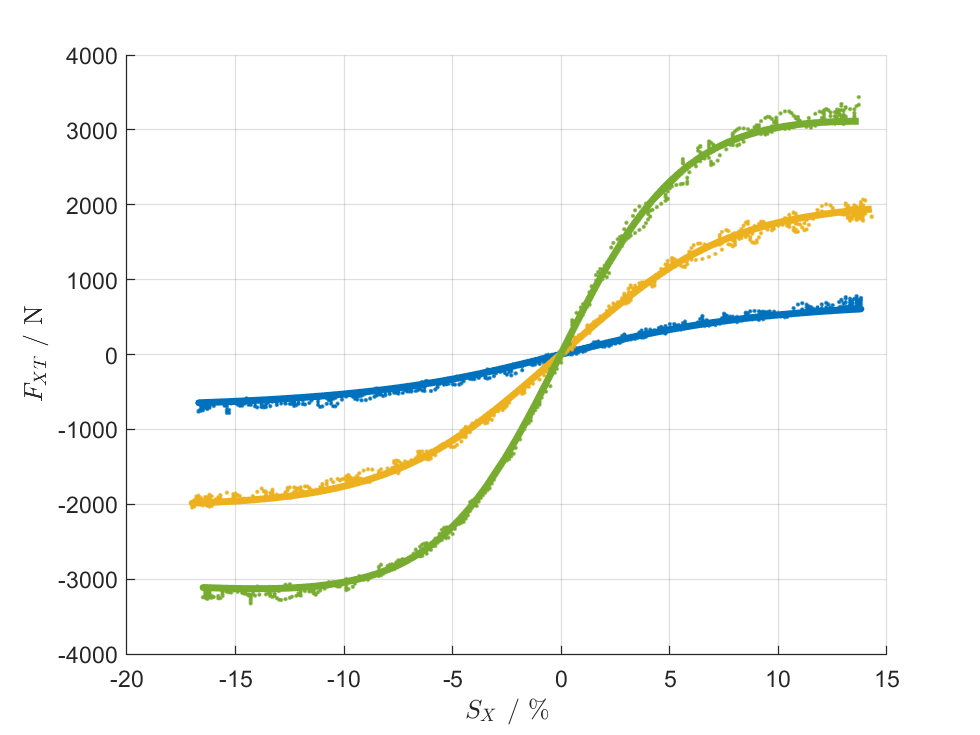

file = fullfile('doc', 'examples', 'fsae-ttc-data', 'fsaettc_obfuscated.tir');
tyre = magicformula.v62.Model(file);

parser = tydex.parsers.FSAETTC_SI_ISO_Mat_DriveBrake;
fileDriveBrake = fullfile('doc', 'examples', 'fsae-ttc-data', 'fsaettc_obscured_testbench_drivebrake.mat');
fileCornering = fullfile('doc', 'examples', 'fsae-ttc-data', 'fsaettc_obscured_testbench_cornering.mat');
measurements1 = tydex.parsers.FSAETTC_SI_ISO_Mat_DriveBrake().run(fileDriveBrake);
measurements2 = tydex.parsers.FSAETTC_SI_ISO_Mat_Cornering().run(fileCornering);
measurementsAll = [measurements1 measurements2];

I = [30 60 133];
measurements = measurementsAll(I);

figure(); grid on; hold on
xlabel('$S_X$ / \%', 'interpreter','latex')
ylabel('$F_{XT}$ / N', 'interpreter','latex')
for i = 1:length(I)
    m = measurements(i);
    IP = m.INFLPRES;
    IA = m.INCLANGL;
    SA = m.SLIPANGL;
    TS = 0;
    FZ = m.FZW;
    SX = m.LONGSLIP;
    FX = m.FX;
    FX_mdl = tyre.eval(SA, SX, IA, IP, FZ, TS);
    h = plot(SX*100, FX_mdl, 'LineWidth', 3);
    plot(SX*100, FX, '.', 'Color', h.Color, 'MarkerSize', 5)
end